# **PROVA FINAL PSI3531 - Processamento de Sinais Aplicado**

## **Guilherme Reis da Silva 10773700**

# QUESTÃO 2 - MARCA D'ÁGUA

## LETRA A

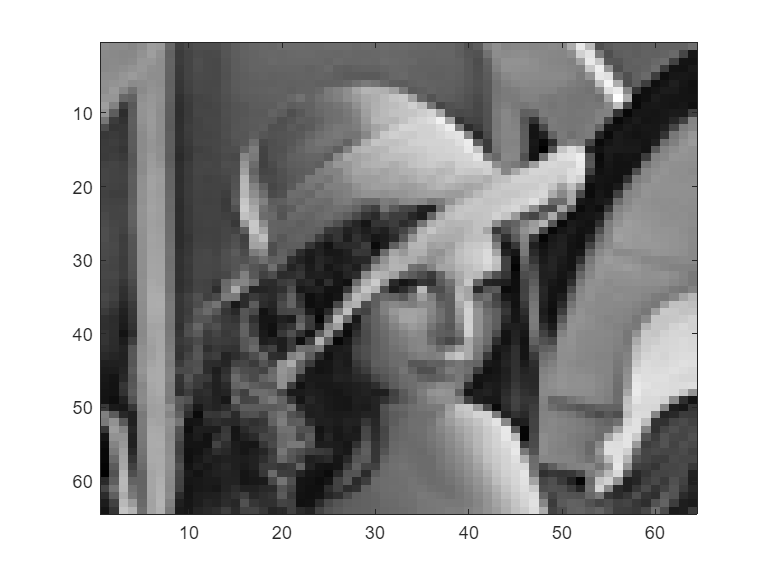

lenna = imread('lenna64.jpg');
imagesc(lenna);
colormap(gray);

M = 64*64*8;

lenna_bin = dec2bin(lenna);
lenna_col = reshape(lenna_bin,2^15,1);
am = 2*str2num(lenna_col) - 1;

fa = 44.1e3;
R = 100;
g = 1;
rand('seed',12345);
Nb = fa / R;

c = 2*round(rand(Nb,1)) - 1; % codigo

v = kron(am,c); % sinal modulado

load('fspecial_matriz.mat')
[musica, fs] = audioread('BeethovenExp5.wav');
x = musica;

w = zeros(length(musica),1);
z = zeros(length(musica),1);
zs = zeros(50,1);
Nblocos = floor(length(musica)/512);

for i = (0:Nblocos-1)
    mascara = psychoacoustical_model( musica(i*512+1 : (i+1)*512) );
    [b0, ai] = shaping_filter_design(mascara, 50);
    [w(i*512+1: (i+1)*512), zs] = filter(b0, ai ,v(i*512+1: (i+1)*512), zs);

    y(i*512+1: (i+1)*512) = w(i*512+1: (i+1)*512) + x(i*512+1: (i+1)*512);
end

zs = zeros(50,1);
for i = (0: floor(length(musica)/512 - 1))
    mascara = psychoacoustical_model( y(i*512+1: (i+1)*512) );
    [b0, ai] = shaping_filter_design(mascara, 50);
    [z(i*512+1: (i+1)*512), zs]= filter(ai, b0 ,y(i*512+1: (i+1)*512), zs);
end

Nfiltro = 50;
correlacao_v= xcorr(v,Nfiltro,'biased');

zs = zeros(2*Nfiltro,1);
pre_dem = zeros(length(musica),1);
saidaWiener = zeros(length(musica),1);

Nblocos = floor(length(musica)/512);

for i = (0: Nblocos-1)
    correlacao_z = xcorr(z(i*512+1: (i+1)*512), 2*Nfiltro, 'biased');
    
    autocorr_z = toeplitz(correlacao_z(2*Nfiltro+1:end));
    
    h = autocorr_z\correlacao_v;
    
    [saidaWiener(i*512+1: (i+1)*512), zs] = filter(h,1,z(i*512+1: (i+1)*512), zs);
    pot_Wiener = sum(saidaWiener(i*512+1: (i+1)*512).*saidaWiener(i*512+1: (i+1)*512))/512;
    
    if pot_Wiener > 0
        saidaWiener(i*512+1: (i+1)*512) = saidaWiener(i*512+1: (i+1)*512)/sqrt(pot_Wiener);
    end
    
end

pre_dem(1:end-Nfiltro) = saidaWiener(Nfiltro+1:end);

ym = reshape(pre_dem,Nb,32768);

alfam = transpose(ym)*c/Nb;
BER = sum(abs(sign(alfam) - am)/2)/length(am)

BER = 0.1161


b_chapeu = sign(alfam);
lenna_col_chapeu = num2str((b_chapeu + 1)/2,"%1.0f");

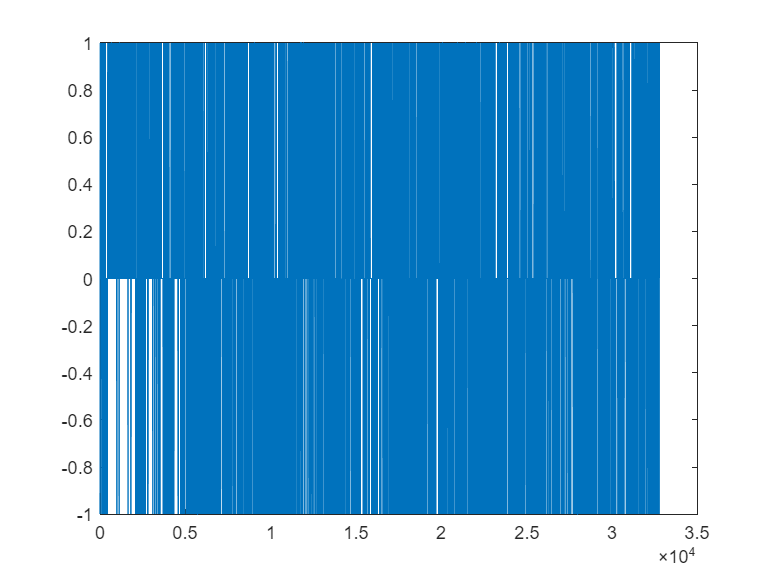

plot(lenna_col_chapeu - lenna_col)

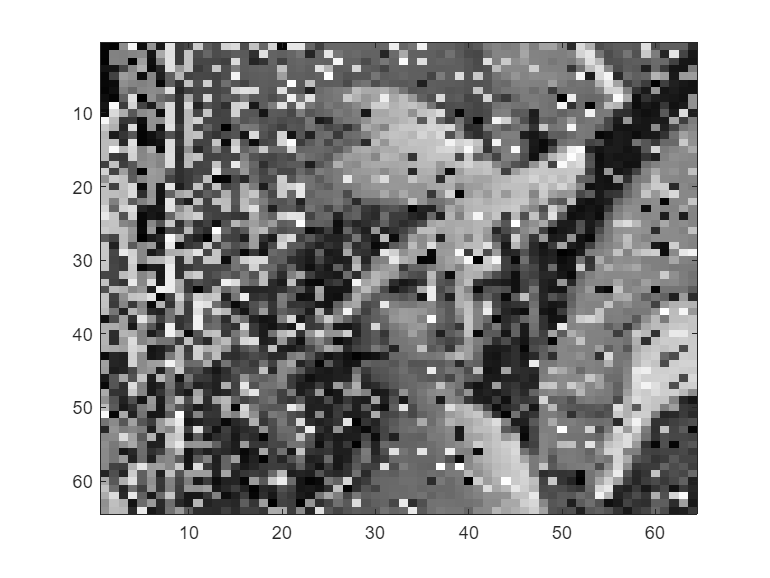

lenna_bin_chapeu = reshape(lenna_col_chapeu, 64*64, 8);
lenna_chapeu = bin2dec(lenna_bin_chapeu);
nova_lenna = reshape(lenna_chapeu, 64,64);

figure()
colormap(gray)
imagesc(nova_lenna)

mssim = ssim_index(lenna, nova_lenna, [0.01 0.03], matriz, 255)

mssim = 0.3761

## LETRA B

musica_mp3 = mp3_codec(y,fs);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To
perform elementwise multiplication, use '.*'.

Error in mp3_codec (line 19)
        subbands(i,:) = (PQMF32_Gfilters*input_frame)';

Related documentation

w = zeros(length(musica_mp3),1);
z = zeros(length(musica_mp3),1);
zs = zeros(50,1);
Nblocos = floor(length(musica_mp3)/512);

for i = (0:Nblocos-1)
    mascara = psychoacoustical_model( musica_mp3(i*512+1 : (i+1)*512) );
    [b0, ai] = shaping_filter_design(mascara, 50);
    [w(i*512+1: (i+1)*512), zs] = filter(b0, ai ,v(i*512+1: (i+1)*512), zs);

    y(i*512+1: (i+1)*512) = w(i*512+1: (i+1)*512) + x(i*512+1: (i+1)*512);
end

% sound(y(fs*5:15*fs),fs)

zs = zeros(50,1);
for i = (0: floor(length(musica_mp3)/512 - 1))
    mascara = psychoacoustical_model( y(i*512+1: (i+1)*512) );
    [b0, ai] = shaping_filter_design(mascara, 50);
    [z(i*512+1: (i+1)*512), zs]= filter(ai, b0 ,y(i*512+1: (i+1)*512), zs);
end

Nfiltro = 50;
correlacao_v= xcorr(v,Nfiltro,'biased');

zs = zeros(2*Nfiltro,1);
pre_dem = zeros(length(musica),1);
saidaWiener = zeros(length(musica),1);

Nblocos = floor(length(musica)/512);

for i = (0: Nblocos-1)
    correlacao_z = xcorr(z(i*512+1: (i+1)*512), 2*Nfiltro, 'biased');
    
    autocorr_z = toeplitz(correlacao_z(2*Nfiltro+1:end));
    
    h = autocorr_z\correlacao_v;
    
    [saidaWiener(i*512+1: (i+1)*512), zs] = filter(h,1,z(i*512+1: (i+1)*512), zs);
    pot_Wiener = sum(saidaWiener(i*512+1: (i+1)*512).*saidaWiener(i*512+1: (i+1)*512))/512;
    
    if pot_Wiener > 0
        saidaWiener(i*512+1: (i+1)*512) = saidaWiener(i*512+1: (i+1)*512)/sqrt(pot_Wiener);
    end
    
end

pre_dem(1:end-Nfiltro) = saidaWiener(Nfiltro+1:end);

ym = reshape(pre_dem,Nb,32768);

alfam = transpose(ym)*c/Nb;
BER = sum(abs(sign(alfam) - am)/2)/length(am)

b_chapeu = sign(alfam);
lenna_col_chapeu = num2str((b_chapeu + 1)/2,"%1.0f");

plot(lenna_col_chapeu - lenna_col)

lenna_bin_chapeu = reshape(lenna_col_chapeu, 64*64, 8);
lenna_chapeu = bin2dec(lenna_bin_chapeu);
nova_lenna = reshape(lenna_chapeu, 64,64);

figure()
colormap(gray)
imagesc(nova_lenna)
mssim = ssim_index(lenna, nova_lenna, [0.01 0.03], matriz, 255)

sigmap = 2e-4;
sigmar = 1e-4;
fc = 11e3;
fp = 10e3;
fr = 12e3;
wc = fc*2*pi/fs;
wp = fp*2*pi/fs;
wr = fr*2*pi/fs;

%Calculo da ordem do Filtro Passa Baixa de Parks-McClallen
% N = ((-10 * log10(sigmar * sigmap)) - 13)/(2.324 * (wr - wp));
% N = N + 1;
% N = round(N);

h = firpm(Nfiltro, [0 wp/pi wr/pi 1], [1 1 0 0], [1 sigmap/sigmar]);

freqz(h,1,512,fs);

c = 2*round(rand(Nb + Nfiltro/2,1)) - 1; % codigo pseudoAleatorio novo
c_intermediario = filter(h,1,c);

clear c2;
c = c_intermediario(Nfiltro/2 + 1: end);
c = sign(c);
pot_c = sum(c.*c)/Nb;
clear c2_intermediario;


v = kron(am,c); % sinal modulado
bm_exp = kron(am, ones(Nb,1)); %repetir cada ponto do am Nb vezes

w = zeros(length(musica_mp3),1);
z = zeros(length(musica_mp3),1);
zs = zeros(50,1);
Nblocos = floor(length(musica_mp3)/512);

for i = (0:Nblocos-1)
    mascara = psychoacoustical_model( musica_mp3(i*512+1 : (i+1)*512) );
    mascara(end/2 +1: end) = -100;
    [b0, ai] = shaping_filter_design(mascara, 50);
    [w(i*512+1: (i+1)*512), zs] = filter(b0, ai ,v(i*512+1: (i+1)*512), zs);

    y(i*512+1: (i+1)*512) = w(i*512+1: (i+1)*512) + x(i*512+1: (i+1)*512);
end

plot(mascara)

sound(y(5*fs:20*fs),fs)

zs = zeros(50,1);
y_posFiltro = filter(h,1,[y ; zeros(Nfiltro/2 , 1)]);
y_posFiltro = y_posFiltro(Nfiltro/2 + 1:end);

for i = (0: floor(length(musica)/512 - 1))
    mascara = psychoacoustical_model( y_posFiltro(i*512+1: (i+1)*512) );
    [b0, ai] = shaping_filter_design(mascara, 50);
    [z(i*512+1: (i+1)*512), zs]= filter(ai, b0 ,y_posFiltro(i*512+1: (i+1)*512), zs);
end

Nfiltro = 50;
correlacao_v= xcorr(v,Nfiltro,'biased');

zs = zeros(2*Nfiltro,1);
pre_dem = zeros(length(musica),1);
saidaWiener = zeros(length(musica),1);

Nblocos = floor(length(musica)/512);

for i = (0: Nblocos-1)
    correlacao_z = xcorr(z(i*512+1: (i+1)*512), 2*Nfiltro, 'biased');
    
    autocorr_z = toeplitz(correlacao_z(2*Nfiltro+1:end));
    
    h = autocorr_z\correlacao_v;
    
    [saidaWiener(i*512+1: (i+1)*512), zs] = filter(h,1,z(i*512+1: (i+1)*512), zs);
    pot_Wiener = sum(saidaWiener(i*512+1: (i+1)*512).*saidaWiener(i*512+1: (i+1)*512))/512;
    
    if pot_Wiener > 0
        saidaWiener(i*512+1: (i+1)*512) = saidaWiener(i*512+1: (i+1)*512)/sqrt(pot_Wiener);
    end
    
end

pre_dem(1:end-Nfiltro) = saidaWiener(Nfiltro+1:end);

ym = reshape(pre_dem,Nb,32768);

alfam = transpose(ym)*c/Nb;
BER = sum(abs(sign(alfam) - am)/2)/length(am)

b_chapeu = sign(alfam);
lenna_col_chapeu = num2str((b_chapeu + 1)/2,"%1.0f");

plot(lenna_col_chapeu - lenna_col)

lenna_bin_chapeu = reshape(lenna_col_chapeu, 64*64, 8);
lenna_chapeu = bin2dec(lenna_bin_chapeu);
nova_lenna = reshape(lenna_chapeu, 64,64);

figure()
colormap(gray)
imagesc(nova_lenna)
mssim = ssim_index(lenna, nova_lenna, [0.01 0.03], matriz, 255)
